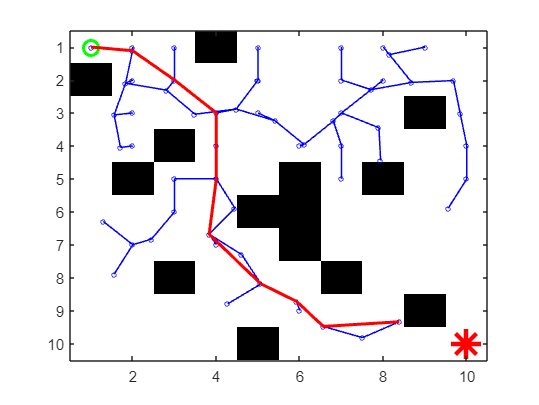

% Define the map
map = [
    0, 0, 0, 1, 0, 0, 0, 0, 0, 0;
    1, 0, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 1, 0;
    0, 0, 1, 0, 0, 0, 0, 0, 0, 0;
    0, 1, 0, 0, 0, 1, 0, 1, 0, 0;
    0, 0, 0, 0, 1, 1, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 1, 0, 0, 0, 0;
    0, 0, 1, 0, 0, 0, 1, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 1, 0;
    0, 0, 0, 0, 1, 0, 0, 0, 0, 0
];

% Define start and goal positions
start = [1, 1];
goal = [10, 10];

% Define RRT parameters
max_iter = 1000; % Maximum number of iterations
step_size = 1.0; % Step size for extending the tree
goal_radius = 2.0; % Radius within which the goal is considered reached

% Initialize the tree with the start node
tree = [start, 0, 0]; % Each node contains x, y, parent index, and cost-to-come

% Plot map
h = figure;
imagesc(map);
colormap(flipud(gray));
hold on;

% Plot start position
plot(start(2), start(1), 'go', 'MarkerSize', 10, 'LineWidth', 2);

% Plot goal position
plot(goal(2), goal(1), 'r*', 'MarkerSize', 20, 'LineWidth', 3);

% Perform RRT*
for iter = 1:max_iter
    % Sample a random point in the map
    random_point = [randi(size(map, 1)), randi(size(map, 2))];

    % Find the nearest node in the tree to the random point
    nearest_node_idx = nearest_neighbor(tree(:, 1:2), random_point);
    nearest_node = tree(nearest_node_idx, :);

    % Extend the tree towards the random point
    new_node = steer(nearest_node(1:2), random_point, step_size);

    % If the new node is not in collision with obstacles
    if ~check_collision(map, nearest_node(1:2), new_node)
        % Find neighbors of the new node within a radius
        near_nodes_idx = find_near_nodes(tree(:, 1:2), new_node, step_size * 2);

        % Choose the parent that results in the lowest cost-to-come
        min_cost = nearest_node(4) + norm(new_node - nearest_node(1:2));
        parent_idx = nearest_node_idx;
        for near_idx = near_nodes_idx'
            near_node = tree(near_idx, :);
            cost = near_node(4) + norm(new_node - near_node(1:2));
            if cost < min_cost && ~any(check_collision(map, near_node(1:2), new_node))
                parent_idx = near_idx;
                min_cost = cost;
            end
        end

        % Add the new node to the tree with the selected parent
        tree(end + 1, :) = [new_node, parent_idx, min_cost];

        % Plot new tree node
        plot(new_node(2), new_node(1), 'bo', 'MarkerSize', 3);

        % Plot new edge
        plot([nearest_node(2), new_node(2)], [nearest_node(1), new_node(1)], 'b', 'LineWidth', 1);

        % Check if the goal is reached
        if norm(new_node - goal) < goal_radius
            path = reconstruct_path(tree, size(tree, 1));
            plot(path(:, 2), path(:, 1), 'r', 'LineWidth', 2);
            break;
        end
    end
    % Pause to show each decision
    pause(0.1);
end

function nearest_node_idx = nearest_neighbor(tree, random_point)
    % Find the index of the nearest node in the tree to the random point
    distances = vecnorm(tree(:, 1:2) - random_point, 2, 2);
    [~, nearest_node_idx] = min(distances);
end

function near_nodes_idx = find_near_nodes(tree, new_node, radius)
    % Find indices of nodes in the tree within a given radius of the new node
    distances = vecnorm(tree(:, 1:2) - new_node, 2, 2);
    near_nodes_idx = find(distances < radius);
end

function new_node = steer(nearest_node, random_point, step_size)
    % Move from the nearest node towards the random point by step_size
    direction = random_point - nearest_node;
    distance = norm(direction);
    if distance <= step_size
        new_node = random_point;
    else
        new_node = nearest_node + (direction / distance) * step_size;
    end
end

function in_collision = check_collision(map, nearest_node, new_node)
    % Check if the line segment between nearest_node and new_node intersects with obstacles
    x1 = nearest_node(1);
    y1 = nearest_node(2);
    x2 = new_node(1);
    y2 = new_node(2);
    
    in_collision = any(map(round(linspace(x1, x2, 100)), round(linspace(y1, y2, 100))));
end

function path = reconstruct_path(tree, goal_idx)
    % Reconstruct the path from the goal node to the start node
    path = tree(goal_idx, 1:2);
    parent_idx = tree(goal_idx, 3);
    while parent_idx ~= 0
        path = [tree(parent_idx, 1:2); path];
        parent_idx = tree(parent_idx, 3);
    end
end